clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

name='Naca2612';
R=50;
lamda_A=7;
z=3;
alpha_A=6;
t=0.25;
r=25

r = 25

edit=1;

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof=profile_transform(R,r,name,lamda_A,z, alpha_A, t)
   else
       prof1=profile_transform(R,r,name,lamda_A,z, alpha_A, t)
       prof=vertcat(prof,prof1)
   end
end

prof =     2.4210    2.4007    2.3655    2.3246    2.2791    2.2303    2.1796    2.1279    2.0755    2.0229    1.9701    1.9173    1.8644    1.8114    1.7584    1.7053    1.6523    1.5993    1.5462    1.4931    1.4401    1.3870    1.3340    1.2809    1.2279    1.1748    1.1216    1.0682    1.0146    0.9610    0.9074    0.8539    0.8004    0.7470    0.6937    0.6405    0.5874    0.5344    0.4816    0.4289    0.3763    0.3239    0.2717    0.2198    0.1680    0.1165    0.0652    0.0143   -0.0364   -0.0866
    0.2002    0.2033    0.2087    0.2147    0.2211    0.2278    0.2343    0.2407    0.2469    0.2528    0.2584    0.2636    0.2685    0.2731    0.2774    0.2814    0.2851    0.2884    0.2914    0.2941    0.2964    0.2984    0.3001    0.3015    0.3025    0.3031    0.3034    0.3034    0.3031    0.3026    0.3018    0.3007    0.2994    0.2978    0.2959    0.2936    0.2911    0.2883    0.2851    0.2815    0.2776    0.2734    0.2687    0.2637    0.2582    0.2523    0.2460    0.2391    0.2318  

## plot

[i,j]=size(prof)

i = 3

j = 160

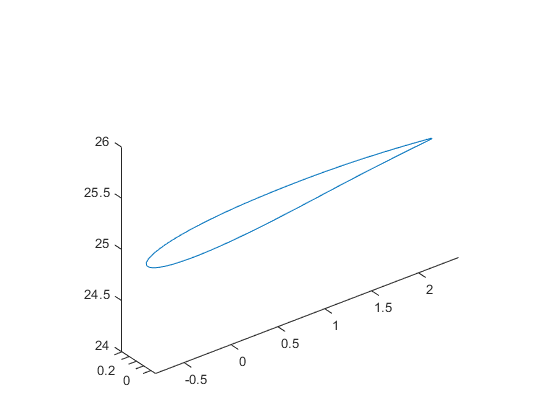

for n=1:3:i
    plot3(prof(n,:),prof(n+1,:),prof(n+2,:))
    hold on
    axis equal
end
hold off